# Effect of filtering in TAPAS rDCM

## Why analyze timeseries in the frequency domain?

One of the main innovations of the rDCM framework used by Frässle et al. in estimating directed connectivity from observed timeseries is to analyze the data not in the time but in the frequency domain.

The conversion of the data in the time domain to the frequency domain using the Fourier transform is a lossless transformation. But viewing the data in the frequency domain can more clearly show the most important parts of the signal.

Even though the frequency domain signal initially has the same length as the data in the time domain filtering out non-infromative components of the signal is easier in the frequency domain and it can lead to much fewer numbers to deal with effectively by setting the magnitude of frequency bins that are below some threshold to 0.

In this notebook we will 

- generate timeseries data for the network used in the `tapas_rdcm_tutorial.m` (see Frässle et al. (2018) for the description of the DCM structure), 

- focus on the activity of one node, 

- transform it from the time to frequency domain, 

- filter the frequency domain signal to extract only the informationve frequencies and 

- inverse transform the filtered signal  in the frequency domain back to the time domain to see the effect of the filtering.

Read in DCM structure and generate timeseries.

temp = load('tapas-master/rDCM/test/DCM_LargeScaleSmith_model1.mat');
DCM = temp.DCM;
options.SNR             = 3;
options.y_dt            = 0.5;
options.p0_all          = 0.15;  % single p0 value (for computational efficiency)
options.iter            = 100;
options.filter_str      = 5;
options.restrictInputs  = 1;
type = 's';

DCM = tapas_rdcm_generate(DCM, options, options.SNR);
options = tapas_rdcm_set_options(DCM, options, type);

## How to find "informative" frequencies

Select one node's data and Fourier transform it. The Fourier transform yields a vector of the same length as the timeseries. Each entry represents a frequency bin instead of a time point. The magnitude (`abs`) of each (complex-valued) entry is the amplitude of the cosine function at that frequency bin. If this magnitude is low then that frequency bin contributes little to the timeseries. 

node = 1;
Fs = 1/options.y_dt;
y = DCM.y(:, node);
[y_fft, f] = myfft(y, Fs);

Taken from `tapas_rdcm_filter.m:`

- Find the frequency bins from the fixed HRF that has more power than a precision value. The FFT of the HRF is a quickly descending function of frequencies. Frequencies with very little amplitudes in this FFT HRF spectrum will not contribute much to a signal that is convolved/filtered with this HRF.

- Frequency bins outside the range of frequencies that'll be used by the HRF during convolution are treated as "noise"

- y_fft has both real and imaginary components in these "noise" frequency bins

- Find which frequency bins from the real and imaginary parts of y_fft have more power in them than the (amplified) standard deviations of signals in the "noise" bins

- These end up being the the low freqeuncy bins that are much fewer in number than the whole spectrum. 

- The final set of indices used to filter y_fft by setting its values to 0 is made up of three components: 1. (most restrictive) Bins in which there is more power than the amplified standard deviations of the noise bins, 2. Non-noise bins based on the HRF, 3. High pass filter

u_dt   	 = DCM.U.dt;
y_dt     = options.y_dt;
r_dt     = y_dt / u_dt;
h = options.h(1:r_dt:end);

[h_fft, hf] = myfft(h, Fs);

[N, nr] = size(y_fft);

prec = 10^(-4);
% freq which are not smoothed out by convolution
h_idx = abs(h_fft) > prec;
str_idx = h_idx;
%% filtering by comapring to noise variance

% relative threshold of signal compare to noise
thr = options.filter_str;

% real and imaginary signal
y_real = real(y_fft);
y_imag = imag(y_fft);

% get the standard deviation of the signal
if ( sum(~str_idx) > 1 )
    std_real = repmat(std(y_real(~str_idx,:)), N, 1);
    std_imag = repmat(std(y_imag(~str_idx,:)), N, 1);
else
    std_real = zeros(N,nr);
    std_imag = zeros(N,nr);
end

% find indices where real or imaginary signal is above threshold
idx = abs(y_real) > thr*std_real | abs(y_imag) > thr*std_imag;

%% high-pass filter

% specify the frequency
hpf  = 16;
freq = round(7*N/(hpf));

% high-pass filtering
idx_freq = [ones(1+freq, nr); zeros(N - 2*freq - 1, nr); ones(freq, nr)];
idx      = idx & repmat(str_idx, 1, nr) & idx_freq;

Filter the signal with the generated id's

idx(1,:) = 1;

% filter the data
y_fft_filt = y_fft;
y_fft_filt(~idx) = 0;

Inverse transform the filtered power spectrum

new_y = myifft(y_fft_filt, f, Fs);

Plot the effect of filtering: setting the value of frequencies that have very low power to 0.

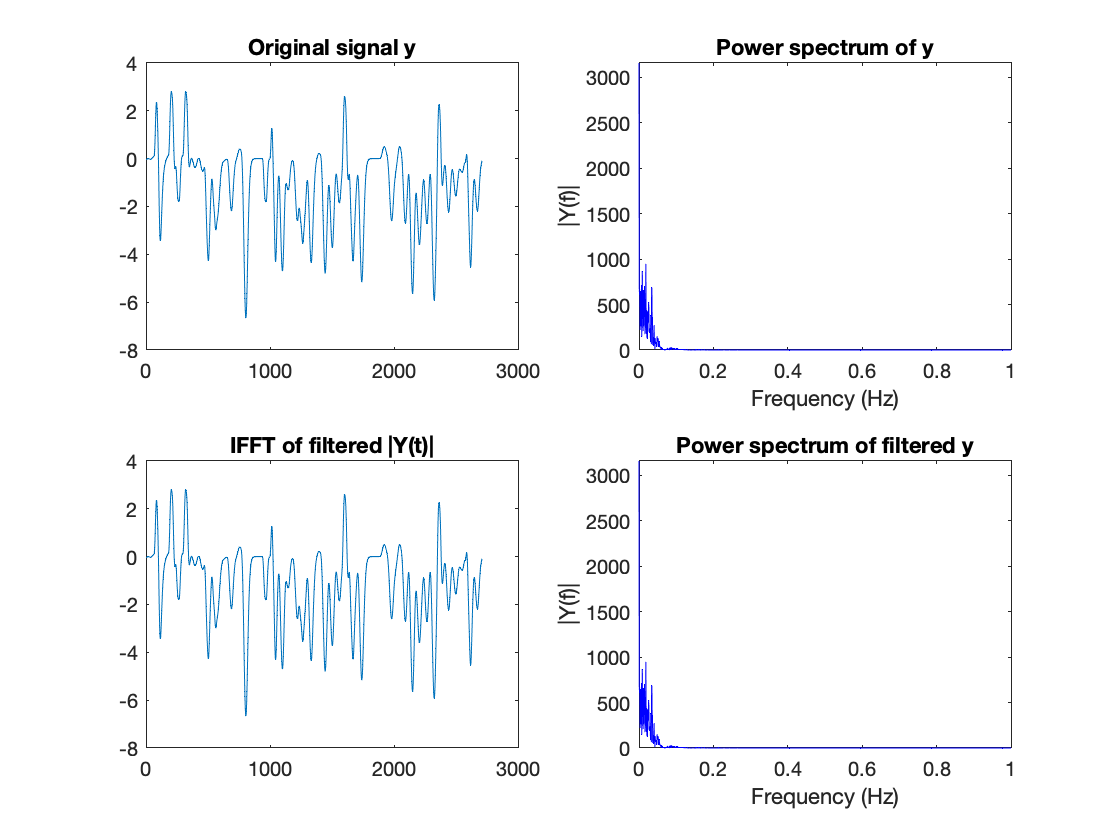

clf
subplot(2,2,1)
plot(1:length(y), y);
title('Original signal y')

subplot(2,2,2)
MagnitudeSpectrumPlot(y_fft, f);
title('Power spectrum of y')

subplot(2,2,4)
MagnitudeSpectrumPlot(y_fft_filt, f);
title('Power spectrum of filtered y')

subplot(2,2,3)

plot(1:length(new_y), new_y);
title('IFFT of filtered |Y(t)|')

ans = 5.6458e-08

Do you loose a lot of information in the time domain? No!

sum((y - new_y).^2)

ans = 44.9926

How much do you reduce the data in the frequency domain? Percentage reduction:

sum(~idx)/length(y_fft)*100